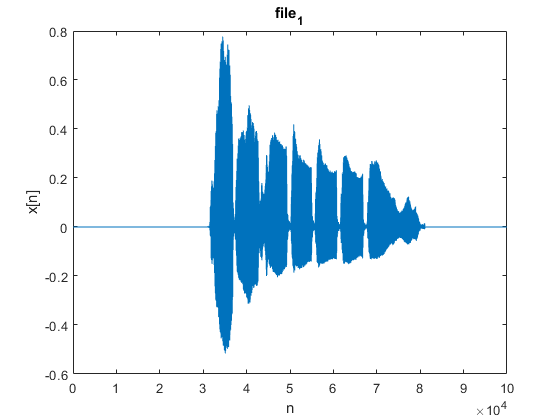

clear all;  
close all;
clc;

[file_1, dS_1] = audioread("trumpet.wav");
[file_2, fs_2] = audioread('telephoneIR.wav');

plot(file_1);
xlabel('n');
ylabel('x[n]');
title('file_1');

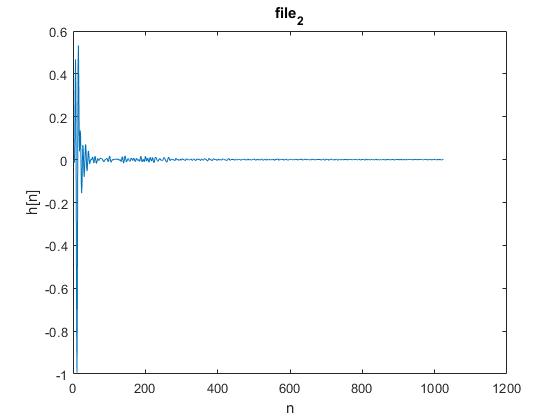

plot(file_2);
xlabel('n');
ylabel('h[n]');
title('file_2');

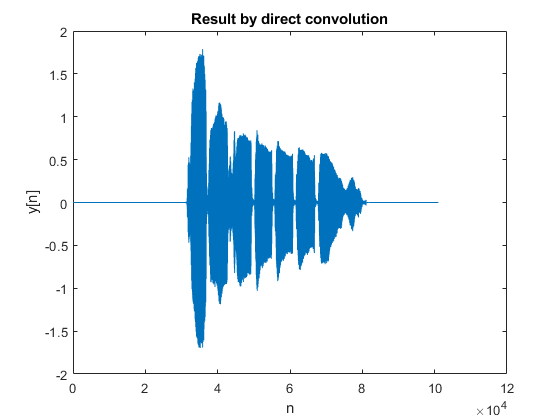

ouput_signal_by_direct = my_direct_convolution(file_1, file_2);
plot(ouput_signal_by_direct);
xlabel('n');
ylabel('y[n]');
title('Result by direct convolution');

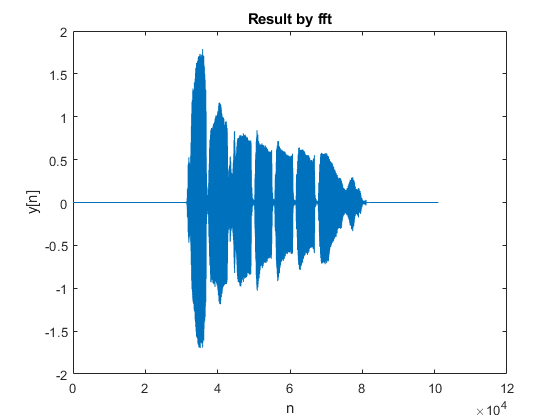


L = length(file_1);
number_of_pad = 2.^ceil(log2(L));
output_signal_by_fft = my_fft_convolution(file_1, file_2, 101023);
plot(output_signal_by_fft);
xlabel('n');
ylabel('y[n]');
title('Result by fft');


test_1 = file_1(1:length(file_2));
test = my_fft_convolution(test_1, file_2, 2*length(file_2)-1)

test =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


clear all;
close all;
clc;

[file_1, fs_1] = audioread("trumpet.wav");
[file_2, fs_2] = audioread('telephoneIR.wav');
N = length(file_1);
K = length(file_2);
final_result = zeros(98, N+K-1);
for i = 1:98
    final_result(i, (i-1)*K+1:(i-1)*K+1+(2*K-2)) = my_fft_convolution(file_1((i-1)*K+1:i*K), file_2, 2*K-1);
end

Index exceeds the number of array elements (100000).